# ECE1150 ASSIGNMENT1 YINHAO QIAN

answer = @(num,unit) fprintf("ANSWER: %f [%s]\n",num,unit);

# Q1

#### For current trends, three topologies are used in typical wired network structure:

- Access Networks, which connects subsribers to their immediate service providers, uses Tree Topology.

- Metro Area Networks uses Ring Topology.

- Backbone Networks, the high speed networks connecting other networks together, uses Mesh Topology.

# Q2_A

#### Star Topology

All nodes are connected to central node.

Advantages: 

- Simpler management

Disadvantages: 

- Susceptible to traffic problems.

- Failure of the central entity causes complete network failure.      

#### Tree Topology

Interconnecting node can be a parent of one or more child nodes.

End device can only be a child node in the tree.

Extend network coverage over star.

Advantages: 

- Easier detection of error

Disadvantages: 

- Difficulty in maintenance and configuration.

#### Ring Topology

All devices are connected in a loop.

Traffic can be unidirectional or bidirectional (Bidirectional could be faster

Advantages: 

- Easy to add devices.

Disadvantage: 

- Communication latency for long routes

#### Mesh Topology

Nodes establish links directly with each other

Advantage: 

- Flexible, more reliable.

Disadvantage: 

- Expensive, harder to manage.

# Q2_B

#### Based on the geographical coverage, networks can be classified as from the smallest coverage to biggest coverage:

Personal Area Network 

Local Area Network

Metropolitan Area Network

Wide Area Network

# Q3_A

#### Packet-Switched Network.

Since many users need to send data, using circuit switching where only one receiver can be communicated might not be a good choice.

# Q3_B

#### Circuit-Switched Network.

Since it will continue running for a relatively long period of time, circuit-switching can eliminate uncessary overheads from packetizations, and resources can be dedicated so that stability is ensured.

# Q4_A

Advantages:

- Allows you to connect with multiple devices

- Network resources are allocated as needed

- Improves link utilization since no resource waste like in circuit switching, yielding 3-100 times more efficient.

- Better suited for bursty traffics or traffic aggregations.

Disadvantages:

- Not ideal for application that requires constannt usage.

- High volume networks could lose data packets during high-traffic hours.

- Lacking safety protocols for data packets

# Q4_B

Each packets has two parts: data to be delivered, and "overhead" that is required for sucessful delivery and integration with other packets.

# Q5_A

clearvars -except answer
P = 10e-6;%[s] per hop proccessing delay
Q_d = 0;%[s] queuing wait time
N_h = 5;%number of hops
N_m = 8;%number of packets
L = 3e3;%[m] length of the link
V = 3e8;%[m/s] velocity of the signal
T_p = L/V; %[s] link propagation delay
M = 1100*8;%[bits] number of bits in each packet
B = 1e6;%[bits/s] bitrate of link
T_t = M/B;%[s] transmission delay per packet
totalDelay = N_h*T_p+N_m*T_t+(N_h-1)*(T_t+P)+Q_d;%[s]
answer(totalDelay,"s");

ANSWER: 0.105690 [s]


# Q5_B

payload = 1000*8*N_m;%[bits]
throughput = payload/totalDelay;
answer(throughput,"bits/s");

ANSWER: 605544.516984 [bits/s]


efficiency = throughput/B;
answer(efficiency*100,"%");

ANSWER: 60.554452 [%]


# Q5_C

clearvars -except answer
T_setupAndDisconnect = 100e-6;%[s]
M = 8000*8;%[bits]
B = 1e6;%[bits/s]
T_t = M/B;%[s]
totalDelay = T_setupAndDisconnect+T_t;
answer(totalDelay,"s");

ANSWER: 0.064100 [s]


# Q5_D

payload = 8000*8;%[bits]
throughput = payload/totalDelay;%[bits/s]
answer(throughput,"bits/s");

ANSWER: 998439.937598 [bits/s]


efficiency = throughput/B;
answer(efficiency*100,"%");

ANSWER: 99.843994 [%]


In this case, circuit-switchig yields way much higher throughput than packet-switching, and same for efficiency.

# Q6

clearvars -except answer
M = 2000*1000*5*8;%[bits]
B = [100e3,1e6,10e6,100e6,1e9];%[bits/s]
T_t = M./B;%[s]
for i = 1:size(T_t,2) 
    answer(T_t(i),"s");
end

ANSWER: 800.000000 [s]
ANSWER: 80.000000 [s]
ANSWER: 8.000000 [s]
ANSWER: 0.800000 [s]
ANSWER: 0.080000 [s]


# Q7_A

Since it's a circuit-swtiching networks, even when the user only uses 10 percent of the time, the network resources will all be reserved for one user at a time:

clearvars -except answer
B_total = 5e6;%[bits/s]
B_user = 200e3;%[bits/s]
N_user = B_total/B_user;%[] 
answer(N_user,"");

ANSWER: 25.000000 []


# Q7_B

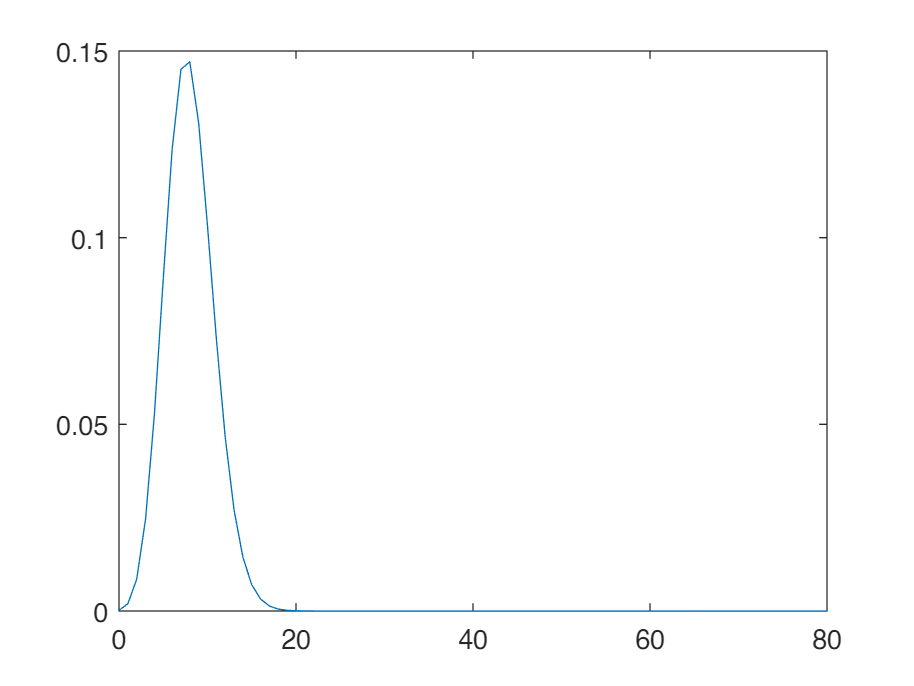

N_user = 0:80;
plot(N_user,binopdf(N_user,80,.1));

We could observe from the probablity density function above that most likely between 0 to 20 users are transmitting data at the same time. It is very unlikely that more than 20 people are tranmitting at the same time.

# Q8_A

clearvars -except answer
syms B;%[bits/s] bitrate
M_forward = 500*8;%[bits] forward file size
M_backward = 100*8;%[bits] backward file size
M_total = M_forward+M_backward;%[bits] total transmission delay
N_h = 2;%[] number of hops
T_p_total = 4e-6;%[s] total propagation delay
totalDelay = 10e-3;%[s] maximum total delay
equation = totalDelay == T_p_total*2 + M_total/B + (N_h-1)*M_total/B;
B = vpasolve(equation,B);%[bits/s] bitrate
answer(B,"bits/s");

ANSWER: 960768.614892 [bits/s]


# Q8_B

syms B;%[bits/s] bitrate
equation = totalDelay == T_p_total*2 + M_total/B + (N_h-1)*M_total/B + 5e-3;
B = vpasolve(equation,B);%[bits/s] bitrate
answer(B,"bits/s");

ANSWER: 1923076.923077 [bits/s]


# Q8_C

Based on the calculation above, we would like to make sure the bitrate does not fall below in Q8_B, and Entry Level DSL is the cheapest option to be on par with the requirement.

# Q9_A

Screenshot:

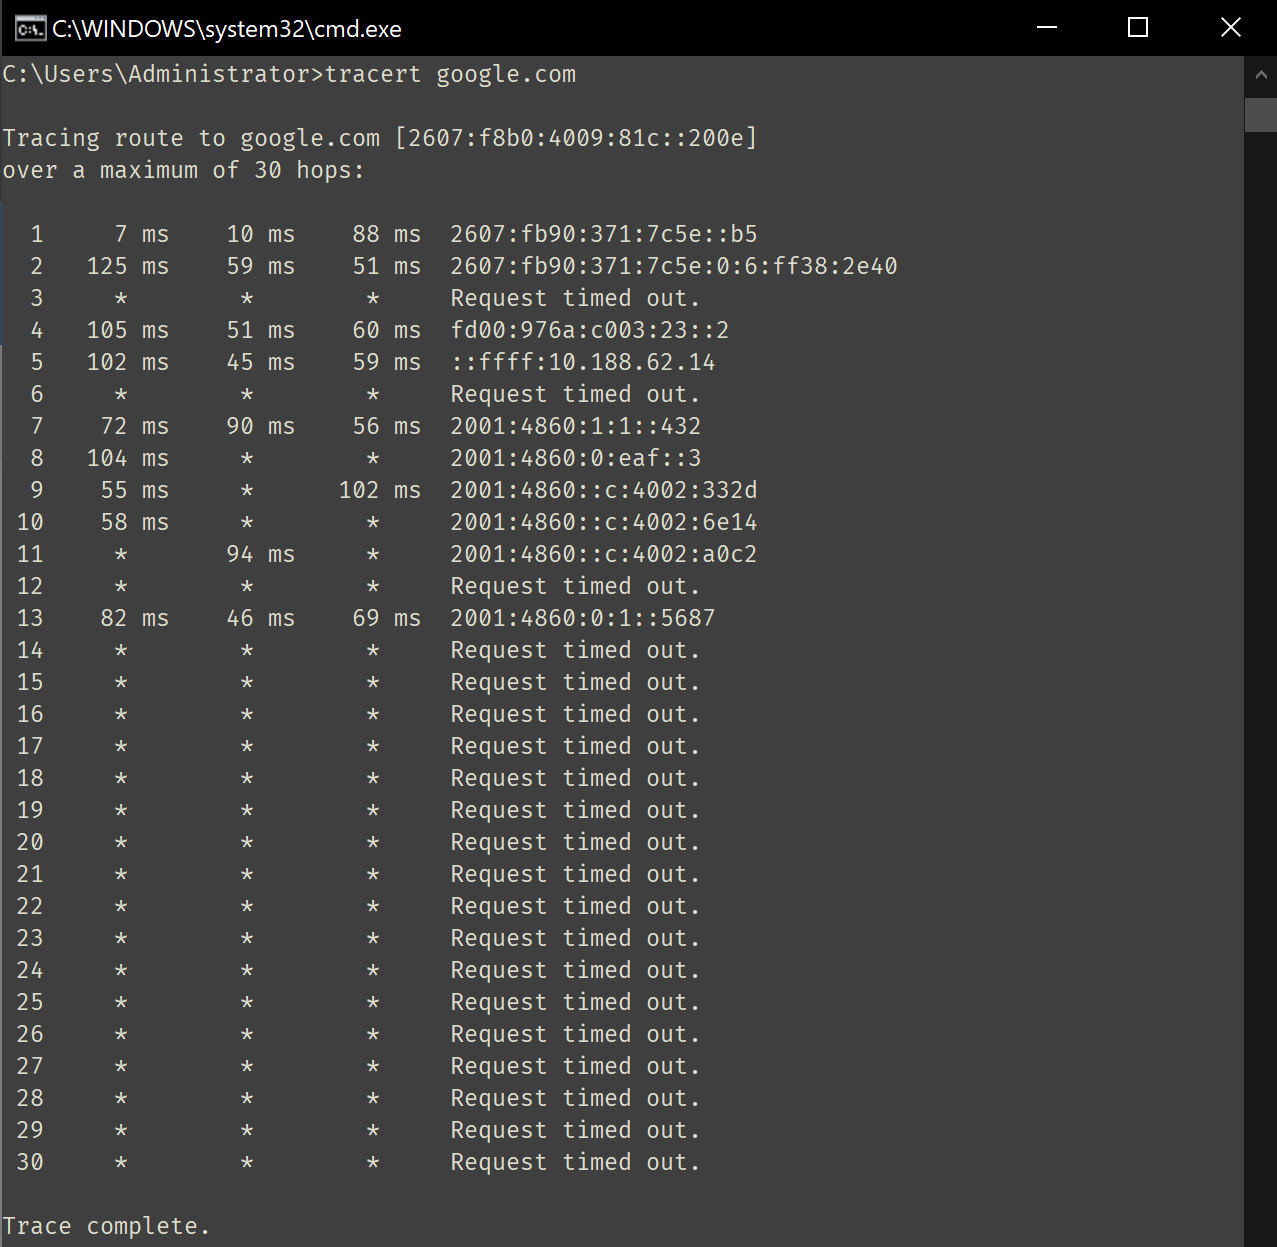

# Q9_B

Although there are many time-outs, we could still see that there are 30 hops that the data has passed through.

export('assi1_subm.mlx','assi1_subm.pdf');